# Example: COVID-2019 data for South korea  (22-Jan-2020 - )

I am taking some data, collected into DATA.mat from John Hopkins university [1]

[1] [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

## Initialisation

The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;

% Download the data from ref [1] and read them with the function getDataCOVID
[tableConfirmed,tableDeaths,tableRecovered,time] = getDataCOVID();
time = time(1:end-1);
fprintf(['Most recent update: ',datestr(time(end)),'\n'])

Most recent update: 23-Mar-2020



try
    indLocation = find(contains(tableRecovered.CountryRegion,'Korea')==1);
catch exception
    searchLoc = strfind(tableRecovered.CountryRegion,'Korea')
    indLocation = find([searchLoc{:}]==1)
end

tableRecovered(indLocation,1:2)

ans = 1×2 table
    ProvinceState    CountryRegion 
    _____________    ______________

      <missing>      "Korea, South"


indLocation = indLocation(1)

indLocation = 158


Recovered = table2array(tableRecovered(indLocation,5:end-1));
Deaths = table2array(tableDeaths(indLocation,5:end-1));
Confirmed = table2array(tableConfirmed(indLocation,5:end-1));

% If the number of confirmed Confirmed cases is small, it is difficult to know whether
% the quarantine has been rigorously applied or not. In addition, this
% suggests that the number of infectious is much larger than the number of
% confirmed cases

minNum= 50;
Recovered(Confirmed<=minNum)=[];
Deaths(Confirmed<=minNum)=[];
time(Confirmed<=minNum)= [];
Confirmed(Confirmed<=minNum)=[];

Npop= 60e6; % population

## Fitting of the generalized SEIR model to the real data

% Definition of the first estimates for the parameters
alpha_guess = 0.06; % protection rate
beta_guess = 1.0; % Infection rate
LT_guess = 5; % latent time in days
QT_guess = 21; % quarantine time in days
lambda_guess = [0.1,0.05]; % recovery rate
kappa_guess = [0.1,0.05]; % death rate

guess = [alpha_guess,...
    beta_guess,...
    1/LT_guess,...
    1/QT_guess,...
    lambda_guess,...
    kappa_guess];


% Initial conditions
E0 = Confirmed(1); % Initial number of exposed cases. Unknown but unlikely to be zero.
I0 = Confirmed(1); % Initial number of infectious cases. Unknown but unlikely to be zero.
Q0 = Confirmed(1);
R0 = Recovered(1);
D0 = Deaths(1);

[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = ...
    fit_SEIQRDP(Confirmed-Recovered-Deaths,Recovered,Deaths,Npop,E0,I0,time,guess);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          9     5.07677e+08                      1.99e+09
     1         18     5.07677e+08       0.346026       1.99e+09      
     2         27     4.79494e+08      0.0865065       2.73e+09      
     3         36     3.92524e+08      0.0216266       1.68e+09      
     4         45     3.46462e+08      0.0432533       2.12e+09      
     5         54     2.84377e+08      0.0865065       9.68e+08      
     6         63     2.03796e+08       0.173013        8.3e+08      
     7         72     1.41943e+08       0.271266       5.64e+08      
     8         81     4.87528e+07       0.252587       1.11e+08      
     9         90     2.11748e+07       0.346026       1.31e+08      
    10         99      9.9605e+06       0.328342       4.74e+07      
    11        108      6.0314e+06       0.177912       1.47e+07      
    12        117      6.0314e+0

## Simulate the epidemy outbreak based on the fitted parameters

dt = 0.1; % time step
time1 = datetime(time(1)):dt:datetime(2020,04,01);
N = numel(time1);
t = [0:N-1].*dt;
[S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t);

## Comparison of the fitted and real data

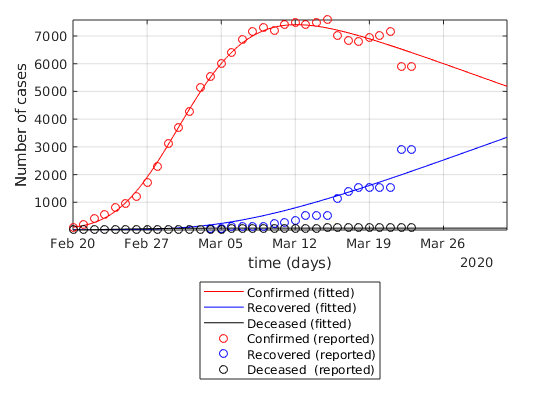

figure
semilogy(time1,Q,'r',time1,R,'b',time1,D,'k');
hold on
semilogy(time,Confirmed-Recovered-Deaths,'ro',time,Recovered,'bo',time,Deaths,'ko');
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('time (days)')
leg = {'Confirmed (fitted)',...
        'Recovered (fitted)','Deceased (fitted)',...
        'Confirmed (reported)','Recovered (reported)','Deceased  (reported)'};
legend(leg{:},'location','southoutside')
set(gcf,'color','w')
grid on
axis tight
% ylim([1,8e4])
 set(gca,'yscale','lin')